# Iterative Solvers for the 1D Poisson Problem

Comparison of Jacobi, Gauss-Seidel and SOR on the 1D Poisson problem

discretised with the standard 3-point central difference stencil. Exact solution: u(x) = 0.5 * x * (1 - x).

Each section below is self-contained: it can be run after the Setup section by clicking Run Section in the MATLAB Live Editor.

## Setup: problem definition and parameters

Build the tridiagonal matrix A, right-hand side b, exact solution u_exact, and the optimal SOR relaxation parameter omega_opt = 2/(1 + sin(pi*h)).

clear; clc; close all;

n     = 50;
h     = 1 / (n + 1);
tol   = 1e-8;
maxit = 20000;

e  = ones(n, 1);
A  = spdiags([-e, 2*e, -e], -1:1, n, n);
b  = h^2 * ones(n, 1);
x0 = zeros(n, 1);

xgrid   = (1:n)' * h;
u_exact = 0.5 * xgrid .* (1 - xgrid);

rho_jacobi = cos(pi / (n + 1));
omega_opt  = 2 / (1 + sqrt(1 - rho_jacobi^2));

fprintf('n = %d,  h = %.4f,  tol = %.0e,  omega_opt = %.6f\n', ...
    n, h, tol, omega_opt);

n = 50,  h = 0.0196,  tol = 1e-08,  omega_opt = 1.884018


## Solve and time the three iterative methods (and the direct solver)

Each method is timed with tic/toc. The direct solve via backslash is included as a baseline. All three iterative solutions should match the direct solution to within the prescribed residual tolerance.

tic; 
[x_j, hist_j, it_j]   = jacobi_method(A, b, tol, maxit, x0);             
t_j = toc;
tic; 
[x_gs, hist_gs, it_gs]  = gauss_seidel_method(A, b, tol, maxit, x0);       
t_gs = toc;
tic; 
[x_sor, hist_sor, it_sor] = sor_method(A, b, omega_opt, tol, maxit, x0);     
t_sor = toc;
tic;  
x_direct = A \ b;                                           
t_direct = toc;

fprintf('\n%-15s  %-12s  %-12s  %-12s\n', 'method', 'iters', 'time (s)', 'time/iter (s)');


method           iters         time (s)      time/iter (s)


fprintf('%-15s  %-12d  %-12.4f  %-12.2e\n', 'Jacobi',       it_j,   t_j,   t_j   / it_j);

Jacobi           9653          0.8177        8.47e-05    


fprintf('%-15s  %-12d  %-12.4f  %-12.2e\n', 'Gauss-Seidel', it_gs,  t_gs,  t_gs  / it_gs);

Gauss-Seidel     4828          0.4051        8.39e-05    


fprintf('%-15s  %-12d  %-12.4f  %-12.2e\n', 'SOR',          it_sor, t_sor, t_sor / it_sor);

SOR              189           0.0360        1.91e-04    


fprintf('%-15s  %-12s  %-12.4f\n',          'direct (\\)',  '-',    t_direct);

direct (\\)      -             0.0060      



fprintf('\nAgreement with direct solution (max |x_iter - x_direct|):\n');


Agreement with direct solution (max |x_iter - x_direct|):


fprintf(' Jacobi       = %.2e\n', norm(x_j   - x_direct, inf));

 Jacobi       = 1.42e-09


fprintf(' Gauss-Seidel = %.2e\n', norm(x_gs  - x_direct, inf));

 Gauss-Seidel = 1.41e-09


fprintf(' SOR          = %.2e\n', norm(x_sor - x_direct, inf));

 SOR          = 4.36e-10


## Convergence history

Relative residual `|b - A*x_k`` / ||b`| versus iteration count, on log-log axes. SOR with omega_opt should converge several orders of magnitude faster than Gauss-Seidel, which in turn is about twice as fast as Jacobi.

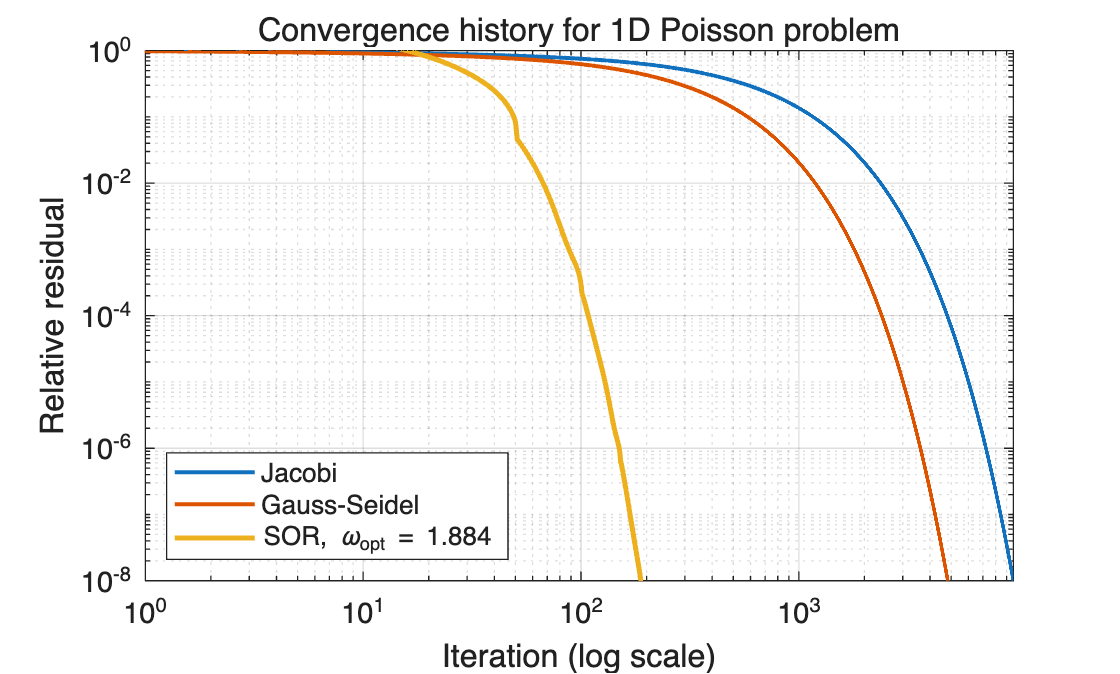

figure('Color', 'w');
loglog(1:it_j,   hist_j(2:end),   'LineWidth', 1.5); hold on;
loglog(1:it_gs,  hist_gs(2:end),  'LineWidth', 1.5);
loglog(1:it_sor, hist_sor(2:end), 'LineWidth', 1.9);
grid on;
xlabel('Iteration (log scale)');
ylabel('Relative residual');
legend('Jacobi', 'Gauss-Seidel', sprintf('SOR, \\omega_{opt} = %.3f', omega_opt), ...
    'Location', 'southwest');
title('Convergence history for 1D Poisson problem');
ylim([tol, 1]);
xlim([1, max(it_j, 2)]);

## Solution profiles at increasing iteration counts

Snapshots of the iterate after 5, 20, and 100 steps, overlaid on the exact solution. Jacobi and Gauss-Seidel are still far from the exact profile at 100 steps; SOR is already visually converged.

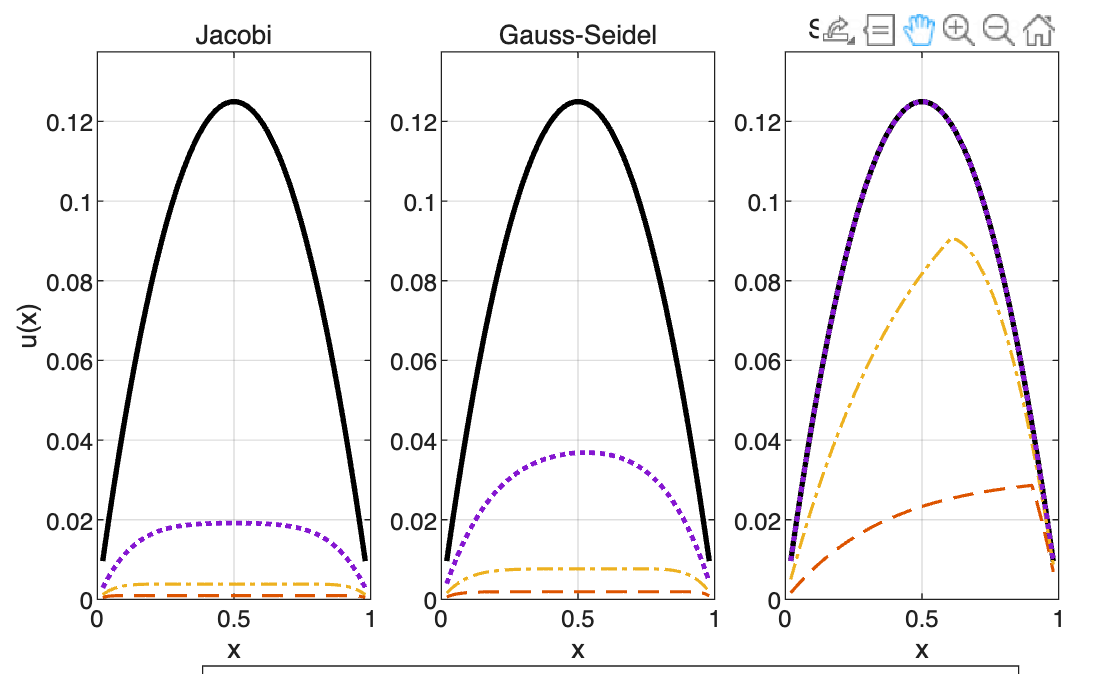

profile_steps = [5, 20, 100];
profiles_j   = profiles_at_steps(A, b, 'jacobi',       1.0,       profile_steps);
profiles_gs  = profiles_at_steps(A, b, 'gauss-seidel', 1.0,       profile_steps);
profiles_sor = profiles_at_steps(A, b, 'sor',          omega_opt, profile_steps);

figure('Color', 'w');
tiledlayout(1, 3, 'Padding', 'compact', 'TileSpacing', 'compact');
methods_label  = {'Jacobi', 'Gauss-Seidel', sprintf('SOR, \\omega_{opt} = %.3f', omega_opt)};
profiles_cell  = {profiles_j, profiles_gs, profiles_sor};

for p = 1:3
    nexttile;
    plot(xgrid, u_exact, 'k-', 'LineWidth', 2); hold on;
    plot(xgrid, profiles_cell{p}(:, 1), '--', 'LineWidth', 1.2);
    plot(xgrid, profiles_cell{p}(:, 2), '-.', 'LineWidth', 1.2);
    plot(xgrid, profiles_cell{p}(:, 3), ':',  'LineWidth', 1.8);
    grid on;
    title(methods_label{p});
    xlabel('x');
    if p == 1
        ylabel('u(x)');
    end
    ylim([0, max(u_exact) * 1.1]);
end
legend({'exact', '5 iterations', '20 iterations', '100 iterations'}, ...
    'Location', 'southoutside', 'Orientation', 'horizontal');

## SOR omega sweep (data for the next figure)

Fine sweep of omega in (0.5, 1.98), recording the iteration count at each value. The minimum is very close to the theoretical omega_opt. The numbers are also printed at a few representative omega values for the slides.

omegas      = linspace(0.5, 1.98, 45);
omega_iters = nan(size(omegas));

for idx = 1:numel(omegas)
    fprintf('omega sweep %2d/%2d: omega = %.3f\n', idx, numel(omegas), omegas(idx));
    [~, ~, omega_iters(idx)] = sor_method(A, b, omegas(idx), tol, maxit, x0);
end

omega sweep  1/45: omega = 0.500
omega sweep  2/45: omega = 0.534
omega sweep  3/45: omega = 0.567
omega sweep  4/45: omega = 0.601
omega sweep  5/45: omega = 0.635
omega sweep  6/45: omega = 0.668
omega sweep  7/45: omega = 0.702
omega sweep  8/45: omega = 0.735
omega sweep  9/45: omega = 0.769
omega sweep 10/45: omega = 0.803
omega sweep 11/45: omega = 0.836
omega sweep 12/45: omega = 0.870
omega sweep 13/45: omega = 0.904
omega sweep 14/45: omega = 0.937
omega sweep 15/45: omega = 0.971
omega sweep 16/45: omega = 1.005
omega sweep 17/45: omega = 1.038
omega sweep 18/45: omega = 1.072
omega sweep 19/45: omega = 1.105
omega sweep 20/45: omega = 1.139
omega sweep 21/45: omega = 1.173
omega sweep 22/45: omega = 1.206
omega sweep 23/45: omega = 1.240
omega sweep 24/45: omega = 1.274
omega sweep 25/45: omega = 1.307
omega sweep 26/45: omega = 1.341
omega sweep 27/45: omega = 1.375
omega sweep 28/45: omega = 1.408
omega sweep 29/45: omega = 1.442
omega sweep 30/45: omega = 1.475
omega swee


selected_omegas = [0.50, 1.00, 1.30, 1.60, omega_opt, 1.95];
fprintf('\nSOR comparison at selected omega values:\n');


SOR comparison at selected omega values:


fprintf(' omega       iterations\n');

 omega       iterations


for idx = 1:numel(selected_omegas)
    [~, ~, selected_iter] = sor_method(A, b, selected_omegas(idx), tol, maxit, x0);
    fprintf('%6.3f       %8d\n', selected_omegas(idx), selected_iter);
end

 0.500          14492
 1.000           4828
 1.300           2595
 1.600           1194
 1.884            189
 1.950            407


fprintf('\nReference iterations:\n');


Reference iterations:


fprintf(' Jacobi       %8d\n', it_j);

 Jacobi           9653


fprintf(' Gauss-Seidel %8d\n', it_gs);

 Gauss-Seidel     4828


## SOR compared with Jacobi and Gauss-Seidel reference lines

Same omega sweep, overlaid with horizontal lines for the Jacobi and Gauss-Seidel iteration counts. SOR matches Gauss-Seidel exactly at omega = 1 and dramatically outperforms both around omega_opt.

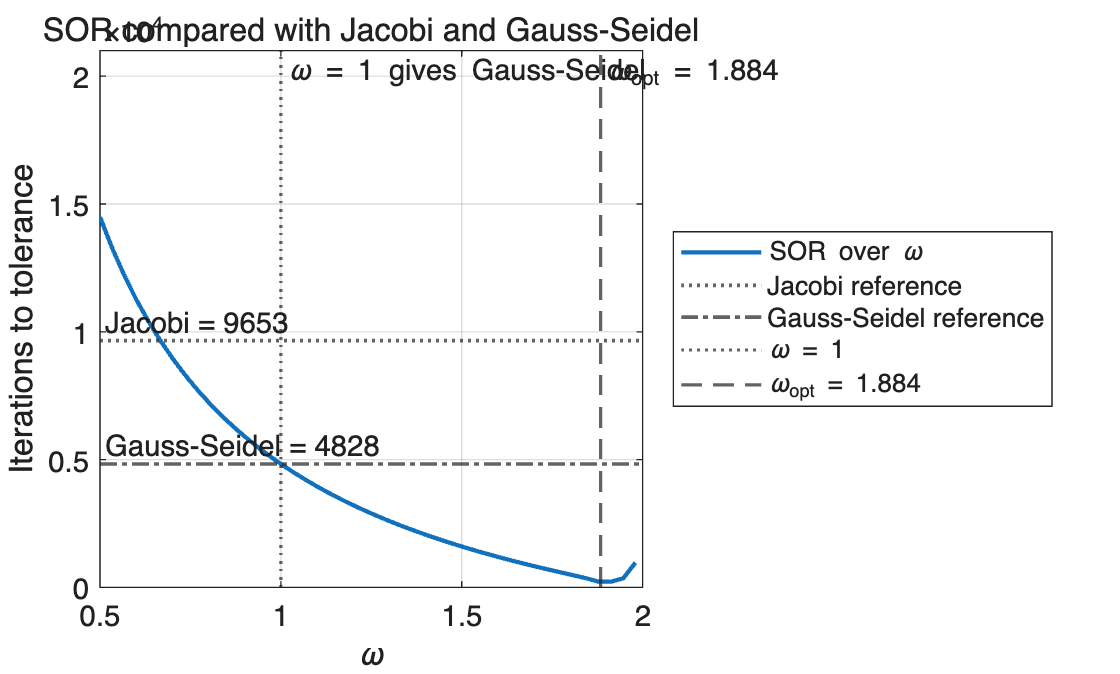

figure('Color', 'w');
h_sor = plot(omegas, omega_iters, 'LineWidth', 1.6); hold on;
h_j   = yline(it_j,  ':',  sprintf('Jacobi = %d', it_j), ...
    'LineWidth', 1.4, 'LabelHorizontalAlignment', 'left');
h_gs  = yline(it_gs, '-.', sprintf('Gauss-Seidel = %d', it_gs), ...
    'LineWidth', 1.4, 'LabelHorizontalAlignment', 'left');
h_one = xline(1.0, ':', '\omega = 1 gives Gauss-Seidel', ...
    'LineWidth', 1.2, 'LabelOrientation', 'horizontal');
h_opt = xline(omega_opt, '--', sprintf('\\omega_{opt} = %.3f', omega_opt), ...
    'LineWidth', 1.2, 'LabelOrientation', 'horizontal');
grid on;
xlabel('\omega');
ylabel('Iterations to tolerance');
title('SOR compared with Jacobi and Gauss-Seidel');
legend([h_sor, h_j, h_gs, h_one, h_opt], ...
    {'SOR over \omega', 'Jacobi reference', 'Gauss-Seidel reference', ...
     '\omega = 1', sprintf('\\omega_{opt} = %.3f', omega_opt)}, ...
    'Location', 'eastoutside');
ylim([0, maxit * 1.05]);

## Scaling study: iteration count vs problem size n

Vary n and record iterations and CPU time for each method. On log-log axes, Jacobi and Gauss-Seidel iteration counts grow like O(n^2), while SOR with the optimal omega grows like O(n). The fitted slopes p are printed below.

ns_scaling    = [10, 20, 40, 80, 160];
iters_scaling = zeros(numel(ns_scaling), 3);
times_scaling = zeros(numel(ns_scaling), 3);

fprintf('\nScaling study (1D Poisson, varying n):\n');


Scaling study (1D Poisson, varying n):


fprintf(' %-6s  %-10s %-10s %-10s   %-10s %-10s %-10s\n', ...
    'n', 'iter_J', 'iter_GS', 'iter_SOR', 't_J (s)', 't_GS (s)', 't_SOR (s)');

 n       iter_J     iter_GS    iter_SOR     t_J (s)    t_GS (s)   t_SOR (s) 



for k = 1:numel(ns_scaling)
    nk  = ns_scaling(k);
    ek  = ones(nk, 1);
    Ak  = spdiags([-ek, 2*ek, -ek], -1:1, nk, nk);
    bk  = (1 / (nk + 1))^2 * ones(nk, 1);
    x0k = zeros(nk, 1);

    rho_Jk      = cos(pi / (nk + 1));
    omega_opt_k = 2 / (1 + sqrt(1 - rho_Jk^2));
    maxit_k     = max(50000, 30 * nk^2);

    tic; [~, ~, iters_scaling(k, 1)] = jacobi_method(Ak, bk, tol, maxit_k, x0k);            times_scaling(k, 1) = toc;
    tic; [~, ~, iters_scaling(k, 2)] = gauss_seidel_method(Ak, bk, tol, maxit_k, x0k);      times_scaling(k, 2) = toc;
    tic; [~, ~, iters_scaling(k, 3)] = sor_method(Ak, bk, omega_opt_k, tol, maxit_k, x0k);  times_scaling(k, 3) = toc;

    fprintf(' %-6d  %-10d %-10d %-10d   %-10.3f %-10.3f %-10.3f\n', ...
        nk, iters_scaling(k, 1), iters_scaling(k, 2), iters_scaling(k, 3), ...
        times_scaling(k, 1), times_scaling(k, 2), times_scaling(k, 3));
end

 10      444        223        40           0.008      0.004      0.001     
 20      1633       818        78           0.053      0.027      0.003     
 40      6238       3120       152          0.454      0.203      0.010     
 80      24354      12178      300          3.229      1.606      0.039     
 160     96217      48110      596          25.390     12.977     0.155     



log_n = log(ns_scaling(:));
p_j   = polyfit(log_n, log(iters_scaling(:, 1)), 1);
p_gs  = polyfit(log_n, log(iters_scaling(:, 2)), 1);
p_sor = polyfit(log_n, log(iters_scaling(:, 3)), 1);
fprintf('\nFitted iter ~ n^p exponents:\n');


Fitted iter ~ n^p exponents:


fprintf(' Jacobi:        p = %.3f  (theory: 2)\n', p_j(1));

 Jacobi:        p = 1.942  (theory: 2)


fprintf(' Gauss-Seidel:  p = %.3f  (theory: 2)\n', p_gs(1));

 Gauss-Seidel:  p = 1.940  (theory: 2)


fprintf(' SOR (opt):     p = %.3f  (theory: 1)\n', p_sor(1));

 SOR (opt):     p = 0.974  (theory: 1)


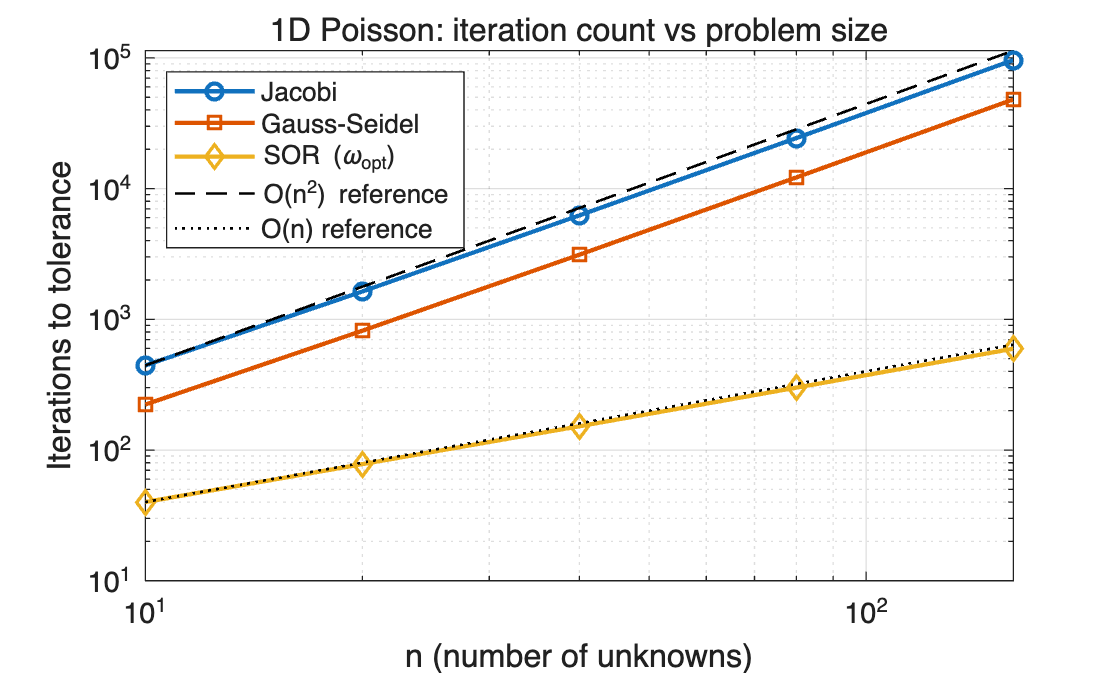


ref_n2 = iters_scaling(1, 1) * (ns_scaling / ns_scaling(1)).^2;
ref_n1 = iters_scaling(1, 3) * (ns_scaling / ns_scaling(1)).^1;

figure('Color', 'w');
loglog(ns_scaling, iters_scaling(:, 1), '-o', 'LineWidth', 1.6); hold on;
loglog(ns_scaling, iters_scaling(:, 2), '-s', 'LineWidth', 1.6);
loglog(ns_scaling, iters_scaling(:, 3), '-d', 'LineWidth', 1.6);
loglog(ns_scaling, ref_n2, 'k--', 'LineWidth', 1.0);
loglog(ns_scaling, ref_n1, 'k:',  'LineWidth', 1.0);
grid on;
xlabel('n (number of unknowns)');
ylabel('Iterations to tolerance');
title('1D Poisson: iteration count vs problem size');
legend({'Jacobi', 'Gauss-Seidel', 'SOR (\omega_{opt})', ...
    'O(n^2) reference', 'O(n) reference'}, 'Location', 'northwest');

## Local helper: profiles_at_steps

Helper for the "Solution profiles" section: runs the chosen iterative method for a list of step counts (no tolerance) and returns one column per step count.

function profiles = profiles_at_steps(A, b, method, omega, requested_steps)
n = length(b);
profiles = zeros(n, numel(requested_steps));
x0 = zeros(n, 1);

for idx = 1:numel(requested_steps)
    step = requested_steps(idx);
    switch lower(method)
        case 'jacobi'
            [x, ~, ~] = jacobi_method(A, b, 0, step, x0);
        case 'gauss-seidel'
            [x, ~, ~] = gauss_seidel_method(A, b, 0, step, x0);
        case 'sor'
            [x, ~, ~] = sor_method(A, b, omega, 0, step, x0);
        otherwise
            error('Unknown method: %s', method);
    end
    profiles(:, idx) = x;
end
end